% datatable81 = unnamed;

Import data table and convert to array

load datatable.mat
data = table2array(datatable);

% p = data(:,1:4)';
% t = data(:,5:6)';
% 
% p1 = p(1,:);
% p2 = p(2,:);
% p3 = p(3,:);
% p4 = p(4,:);
% 
% t1 = t(1,:);
% t2 = t(2,:);
% 
% p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
% p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
% p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
% p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
% t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
% t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));
% 
% pn = [p1n p2n p3n p4n]';
% tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

## hyperparameter optimization (number of neurons)

data = noexten81;
numdata = numel(data(:,1))

numdata = 54

foldsize = ceil(numdata/5);

%% randomize
randata = data(randperm(size(data,1)),:)

randata = 	1.0e+03 *

    0.0010    0.1600    0.5000    0.0050    0.1632    1.7053
    0.0020    0.1400    0.3000    0.0050    0.0772    1.3866
    0.0015    0.1400    0.4000    0.0050    0.0969    1.5801
    0.0015    0.1600    0.4000    0.0050    0.1102    1.4124
    0.0015    0.1600    0.4000    0.0035    0.1102    1.7557
    0.0010    0.1400    0.3000    0.0035    0.1398    1.7428
    0.0015    0.1200    0.3000    0.0050    0.0850    1.5300
    0.0010    0.1400    0.3000    0.0050    0.1398    1.6452
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9465
    0.0015    0.1400    0.5000    0.0050    0.0973    1.7097


%% normalize
normdata = normalize(randata,"range");

fold1 = normdata(1:foldsize,:);
fold2 = normdata(foldsize+1:2*foldsize,:);
fold3 = normdata(2*foldsize+1:3*foldsize,:);
fold4 = normdata(3*foldsize+1:4*foldsize,:);
fold5 = normdata(4*foldsize+1:numdata,:);

f1 = [fold1;fold2;fold3;fold4;fold5]';
f2 = [fold2;fold1;fold3;fold4;fold5]';
f3 = [fold3;fold1;fold2;fold4;fold5]';
f4 = [fold4;fold1;fold2;fold3;fold5]';
f5 = [fold5;fold1;fold2;fold3;fold4]';

valInd = 1:foldsize;
trainInd = foldsize+1:numdata;

for i=1:50
Fcn = 'tansig';
netf1 = fitnet(i,'trainlm');
netf2 = fitnet(i,'trainlm');
netf3 = fitnet(i,'trainlm');
netf4 = fitnet(i,'trainlm');
netf5 = fitnet(i,'trainlm');

netf1.divideFcn = 'divideind';
netf1.divideParam.valInd = 1:foldsize;
netf1.divideParam.trainInd = foldsize+1:numdata;
netf1.inputs{1}.processFcns   = {'removeconstantrows'};
netf1.outputs{2}.processFcns  = {'removeconstantrows'};
netf1.layers{1}.transferFcn = Fcn;

netf2.divideFcn = 'divideind';
netf2.divideParam.valInd = 1:foldsize;
netf2.divideParam.trainInd = foldsize+1:numdata;
netf2.inputs{1}.processFcns   = {'removeconstantrows'};
netf2.outputs{2}.processFcns  = {'removeconstantrows'};
netf2.layers{1}.transferFcn = Fcn;

netf3.divideFcn = 'divideind';
netf3.divideParam.valInd = 1:foldsize;
netf3.divideParam.trainInd = foldsize+1:numdata;
netf3.inputs{1}.processFcns   = {'removeconstantrows'};
netf3.outputs{2}.processFcns  = {'removeconstantrows'};
netf3.layers{1}.transferFcn = Fcn;

netf4.divideFcn = 'divideind';
netf4.divideParam.valInd = 1:foldsize;
netf4.divideParam.trainInd = foldsize+1:numdata;
netf4.inputs{1}.processFcns   = {'removeconstantrows'};
netf4.outputs{2}.processFcns  = {'removeconstantrows'};
netf4.layers{1}.transferFcn = Fcn;

netf5.divideFcn = 'divideind';
netf5.divideParam.valInd = 1:foldsize;
netf5.divideParam.trainInd = foldsize+1:numdata;
netf5.inputs{1}.processFcns   = {'removeconstantrows'};
netf5.outputs{2}.processFcns  = {'removeconstantrows'};
netf5.layers{1}.transferFcn = Fcn;

[netf1,trf1] = train(netf1,f1(1:4,:),f1(5:6,:));
[netf2,trf2] = train(netf2,f2(1:4,:),f2(5:6,:));
[netf3,trf3] = train(netf3,f3(1:4,:),f3(5:6,:));
[netf4,trf4] = train(netf4,f4(1:4,:),f4(5:6,:));
[netf5,trf5] = train(netf5,f5(1:4,:),f5(5:6,:));
err(i) =(trf1.best_vperf+trf2.best_vperf+trf3.best_vperf+trf4.best_vperf+trf5.best_vperf)/5;
end

plot(err);
[M0,I0] = min(err);
disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

     5



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0041



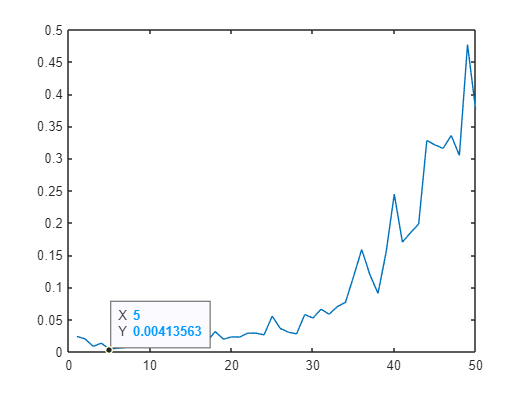

hold off;

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

plot(mse_val0,'-');

disp('training index of best MSE value set is')
disp(I0)
disp('Which has MSE =')
disp(M0)
hold off;

net1 = fitnet(5,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'tansig';

[net1,tr1] = train(net1,f1(1:4,:),f1(5:6,:));

input = normalize(noexten81(:,1:4),'range');
output_ANN1 = net1(input')

output_ANN1 =     0.5401    0.5545    0.5617    0.5554    0.5951    0.5839    0.7455    0.7517    0.7520    0.7523    0.7888    0.7761    0.9930    0.9919    0.9822    0.9940    1.0148    1.0045    0.1982    0.1962    0.1900    0.1843    0.2015    0.1926    0.3334    0.3355    0.3201    0.3158    0.3213    0.3136    0.4805    0.4903    0.4853    0.4831    0.4780    0.4726    0.0442    0.0475    0.0297    0.0284    0.0040   -0.0011    0.1070    0.1113    0.1102    0.1114    0.0946    0.0921    0.1816    0.1830
    0.3056    0.5730    0.2107    0.5607    0.2014    0.7380    0.4462    0.4713    0.1869    0.5280    0.1597    0.7371    0.6356    0.3127    0.2022    0.3565    0.1033    0.4572    0.5357    0.3572    0.3262    0.4791    0.2661    0.7320    0.6981    0.2633    0.4264    0.3155    0.2576    0.5012    0.6769    0.1639    0.5406    0.1754    0.2869    0.1778    0.8671    0.3114    0.6951    0.4794    0.4248    0.5628    0.7712    0.1021    0.7507    0.3079    0.5642    0.3785    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   118.1468  119.5558  120.2612  119.6448  123.5398  122.4359  138.2690  138.8751  138.9113  138.9398  142.5131  141.2686  162.5194  162.4180  161.4678  162.6232  164.6622  163.6451   84.6452   84.4494   83.8396   83.2856   84.9746   84.0982   97.8921   98.1014   96.5914   96.1730   96.7081   95.9510  112.3022  113.2709  112.7785  112.5593  112.0579  111.5291   69.5559   69.8845   68.1384   68.0107   65.6231   65.1213   75.7137   76.1291   76.0247   76.1382   74.4966   74.2490   83.0255   83.1621


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    1.5366    1.7936    1.4454    1.7818    1.4365    1.9521    1.6717    1.6958    1.4226    1.7503    1.3963    1.9513    1.8537    1.5434    1.4372    1.5856    1.3422    1.6823    1.7577    1.5862    1.5564    1.7033    1.4986    1.9464    1.9138    1.4959    1.6527    1.5461    1.4904    1.7245    1.8934    1.4004    1.7624    1.4115    1.5186    1.4138    2.0762    1.5422    1.9109    1.7036    1.6511    1.7838    1.9841    1.3411    1.9643    1.5388    1.7852    1.6066    1.6982    1.2526


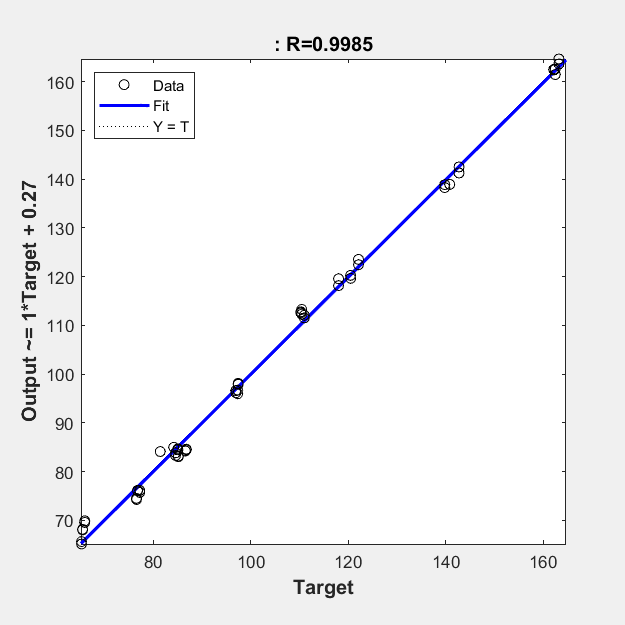

plotregression(noexten81(:,5),ANNIPF');

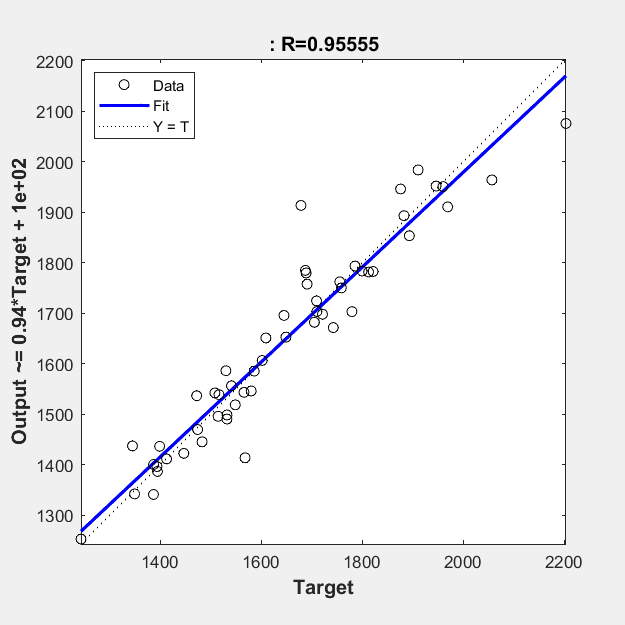

plotregression(noexten81(:,6),ANNSEA');


% plotregression(t1n,output_ANN1(1,:));
% plotregression(t2n,output_ANN1(2,:));


pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.3529
    0.4768



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 99.8086

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.7011e+03


maxipf=max(data(:,5))

maxipf = 163.2074

minipf=min(data(:,5))

minipf = 65.2277

maxsea=max(data(:,6))

maxsea = 2.2039e+03

minsea=min(data(:,6))

minsea = 1.2429e+03

## ANN function test unit

data = noexten81

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0035    0.1180    1.4721
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7859
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4828
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8128
    0.0010    0.1200    0.5000    0.0035    0.1221    1.3987
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9465
    0.0010    0.1400    0.3000    0.0035    0.1398    1.7428
    0.0010    0.1400    0.3000    0.0050    0.1398    1.6452
    0.0010    0.1400    0.4000    0.0035    0.1408    1.4466
    0.0010    0.1400    0.4000    0.0050    0.1408    1.7588


testing(:,1) = (testingdata(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
testing(:,2) = (testingdata(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
testing(:,3) = (testingdata(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
testing(:,4) = (testingdata(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));

x = testing(:,1:4);
x = normalize(data(:,1:4),"range");
Y = net1(x');
Y(1,:) = ((Y(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

Y =   118.1468  119.5558  120.2612  119.6448  123.5398  122.4359  138.2690  138.8751  138.9113  138.9398  142.5131  141.2686  162.5194  162.4180  161.4678  162.6232  164.6622  163.6451   84.6452   84.4494   83.8396   83.2856   84.9746   84.0982   97.8921   98.1014   96.5914   96.1730   96.7081   95.9510  112.3022  113.2709  112.7785  112.5593  112.0579  111.5291   69.5559   69.8845   68.1384   68.0107   65.6231   65.1213   75.7137   76.1291   76.0247   76.1382   74.4966   74.2490   83.0255   83.1621
    0.3056    0.5730    0.2107    0.5607    0.2014    0.7380    0.4462    0.4713    0.1869    0.5280    0.1597    0.7371    0.6356    0.3127    0.2022    0.3565    0.1033    0.4572    0.5357    0.3572    0.3262    0.4791    0.2661    0.7320    0.6981    0.2633    0.4264    0.3155    0.2576    0.5012    0.6769    0.1639    0.5406    0.1754    0.2869    0.1778    0.8671    0.3114    0.6951    0.4794    0.4248    0.5628    0.7712    0.1021    0.7507    0.3079    0.5642    0.3785    0.4738    0

Y(2,:) = ((Y(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

Y = 	1.0e+03 *

    0.1181    0.1196    0.1203    0.1196    0.1235    0.1224    0.1383    0.1389    0.1389    0.1389    0.1425    0.1413    0.1625    0.1624    0.1615    0.1626    0.1647    0.1636    0.0846    0.0844    0.0838    0.0833    0.0850    0.0841    0.0979    0.0981    0.0966    0.0962    0.0967    0.0960    0.1123    0.1133    0.1128    0.1126    0.1121    0.1115    0.0696    0.0699    0.0681    0.0680    0.0656    0.0651    0.0757    0.0761    0.0760    0.0761    0.0745    0.0742    0.0830    0.0832
    1.5366    1.7936    1.4454    1.7818    1.4365    1.9521    1.6717    1.6958    1.4226    1.7503    1.3963    1.9513    1.8537    1.5434    1.4372    1.5856    1.3422    1.6823    1.7577    1.5862    1.5564    1.7033    1.4986    1.9464    1.9138    1.4959    1.6527    1.5461    1.4904    1.7245    1.8934    1.4004    1.7624    1.4115    1.5186    1.4138    2.0762    1.5422    1.9109    1.7036    1.6511    1.7838    1.9841    1.3411    1.9643    1.5388    1.7852    1.6066   

plotregression(data(:,5), Y(1,:));

plotregression(data(:,6), Y(2,:));

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.

Y = poslin144(R);